# Robo HW 7

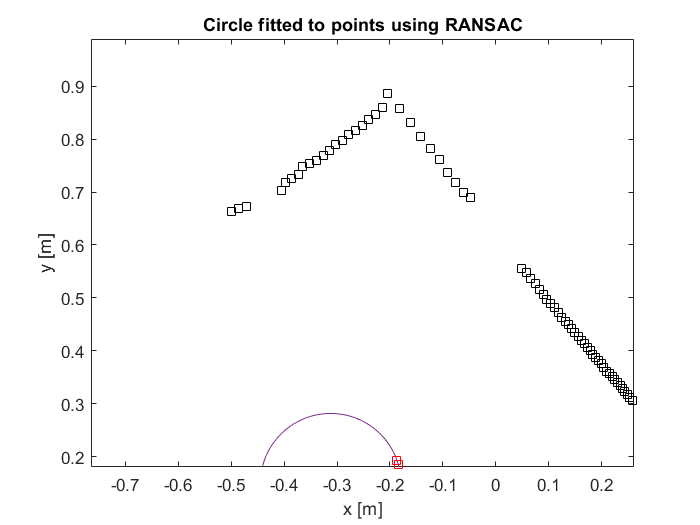

clf; clc; clear;

load playpensample.mat
known_radius = 0.1329;

% eliminate zeros
index = find(r~=0 & r<3);
r_clean = r(index);
theta_clean = theta(index);

% conver to cartesian
[x, y] = pol2cart(deg2rad(theta_clean),r_clean);
points = [x, y];
% example points
% points = [0, 1; 2, 5; 1, 6; 7, 6];

% set threshold and number of times to try algorithm
d = 0.01;
n = 1000;

bestCenterPoint = [];
bestRadius = 0;
bestInlierSet = zeros(0,2);
bestOutlierSet = zeros(0,2);
for i=1:n
    
    % have a set radius
    if known_radius > 0
        seedPoints = datasample(points,2,'Replace', false);
        [center,r] = fitCircle2(seedPoints, known_radius);
        if isnan(center)
            continue;
        end
    else
        % select three points and fit a circle to the points
        seedPoints = datasample(points,3,'Replace',false);
        [px,py,r] = fitCircle3(seedPoints);
        center = [px py];
    end
    diffs = points - repmat([center(1), center(2)], [size(points, 1) 1]);
    radii = sqrt(sum(diffs.^2,2));
    inliers = abs(radii - r) < d;

    % probably deal with gaps
    
    if sum(inliers) > size(bestInlierSet, 1)
        bestCenterPoint = center;
        bestRadius = r;
        bestInlierSet = points(inliers,:); % set inliers
        bestOutlierSet = points(~inliers,:); % set outliers
    end
end

syms x y
circle_equation_explicit = (x-bestCenterPoint(1))^2 + (y-bestCenterPoint(2))^2 == bestRadius^2;

% plot center point
plot(bestCenterPoint(1), bestCenterPoint(2), '.'); hold on;

% plot inliers
plot(bestInlierSet(:,1),bestInlierSet(:,2), 'rs');

% plot outliers
plot(bestOutlierSet(:,1),bestOutlierSet(:,2), 'ks');

% plot circle
fimplicit(circle_equation_explicit,[-4*pi 4*pi]); axis equal;
title('Circle fitted to points using RANSAC')
xlabel('x [m]')
ylabel('y [m]')